# Plot Sensitivities

- Load the symbolic char parameters and the sensitivities to plot

- Plot Sensitivities

#### Step 1

clear; 
clear all;

Parameters;
load("mats/SIE_X_Means.mat", "SIE_X_Means");
load("mats/SIE_X_Sensitivities.mat", "SIE_X_Sens");
load("mats/AIE_X_Means.mat", "AIE_X_Means");
load("mats/AIE_X_Sensitivities.mat", "AIE_X_Sens");


muscles = {'DELT1', 'DELT2', 'DELT3', 'PECM2', 'BIClong', 'BICshort', 'TRIlong', 'TRIlat', 'BRA', 'BRD', 'PT', 'FCR', 'FCU', 'ECR', 'ECU'};
muscle = {1, muscles{1}};

#### Step 2

Now that we have loaded the sensitivities and necessary character values, we can plot the:

- SIE and AIE sensitivies

- Means of SIE and AIE - Heatmap, ascending order of parameter influence

#### SIE and AIE Sensitivities

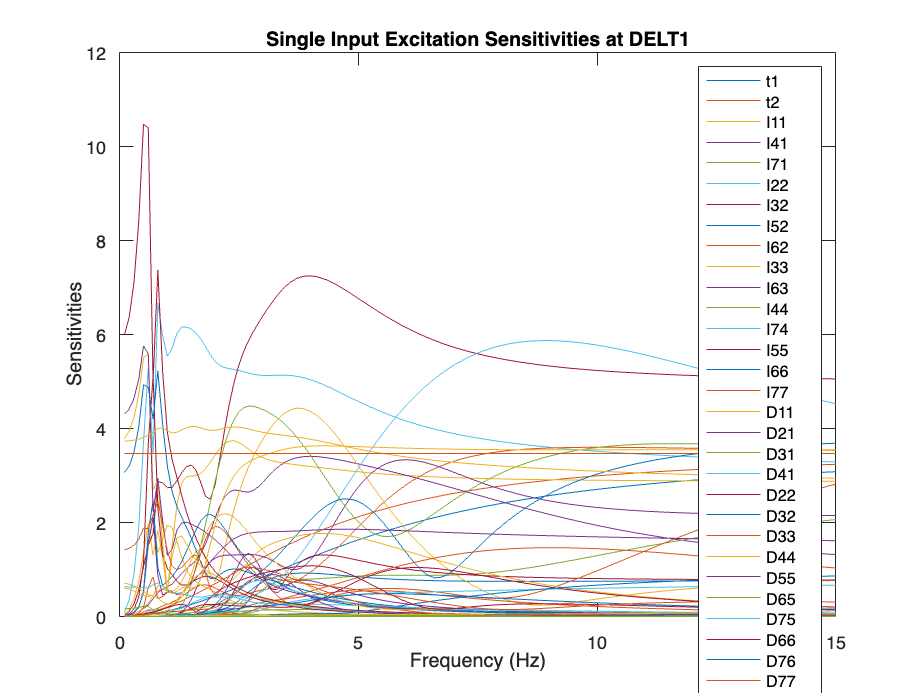

% SIE and AIE
sens_x_plot(SIE_X_Sens, "Single Input Excitation Sensitivities at " + muscle{2}, params_char, muscle{1});

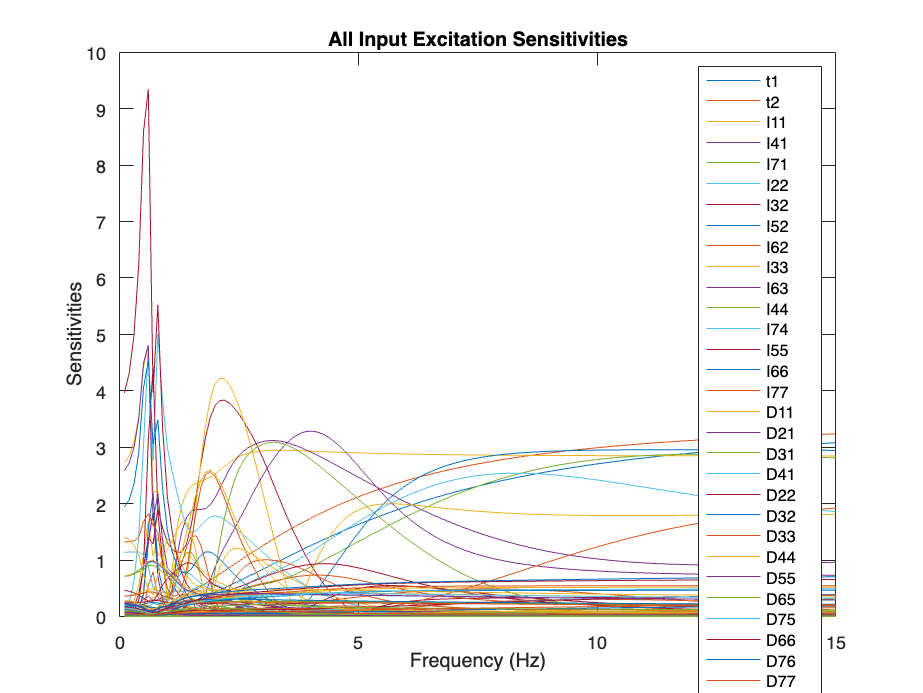

sens_x_plot(AIE_X_Sens, "All Input Excitation Sensitivities", params_char, 0);

We just plotted the sensitivities, now lets plot their means so we can analyze which parameters have the most effect in the tremor band.

#### SIE and AIE Mean Sensitivities

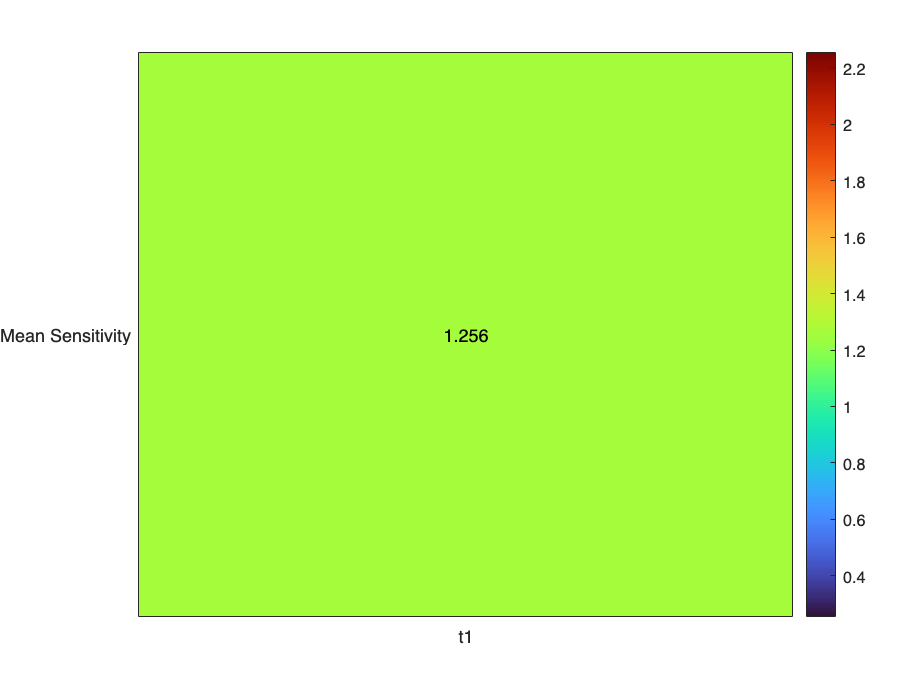

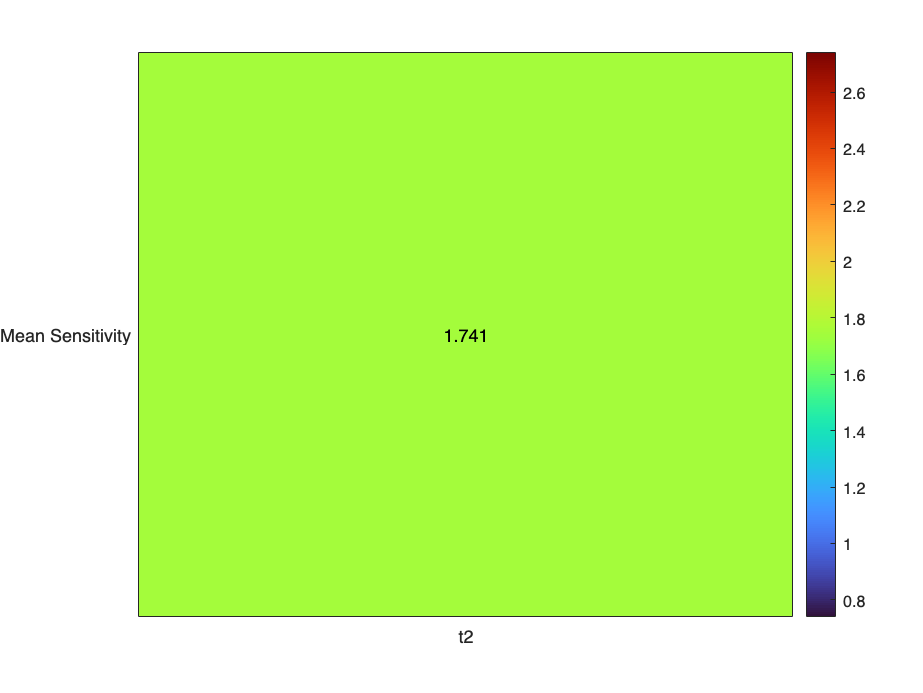

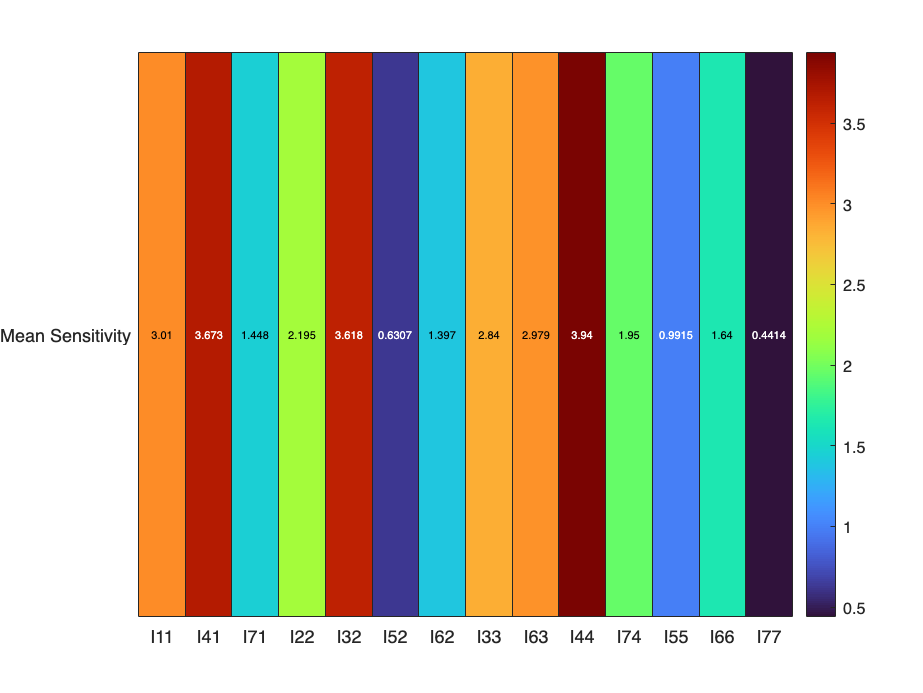

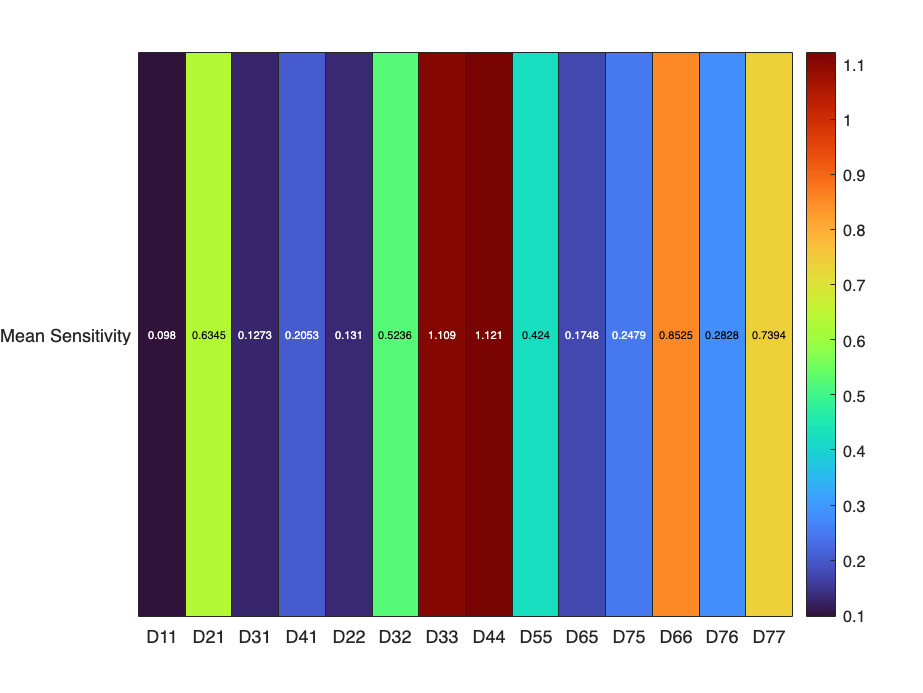

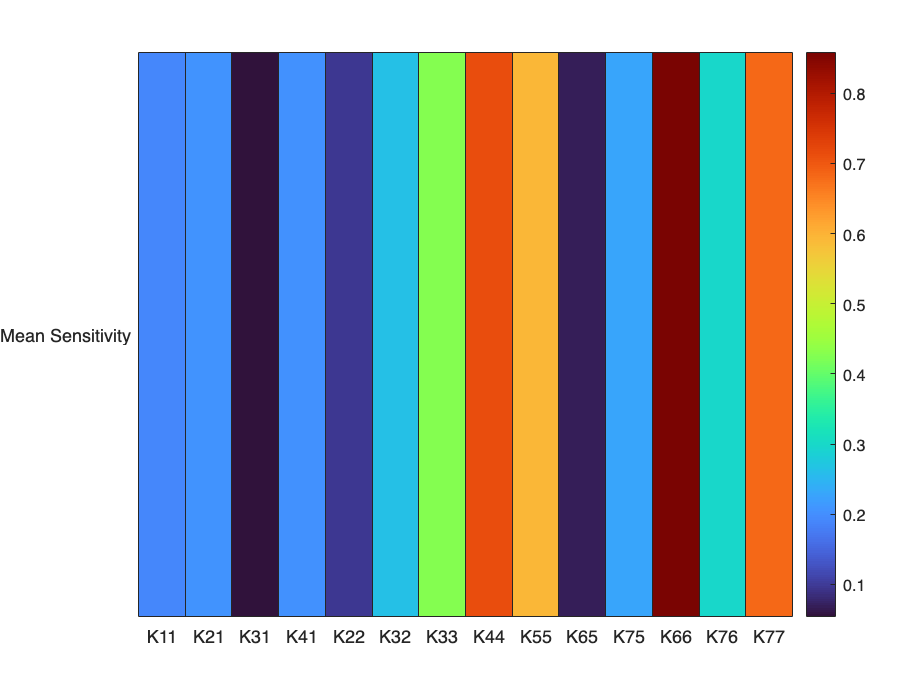

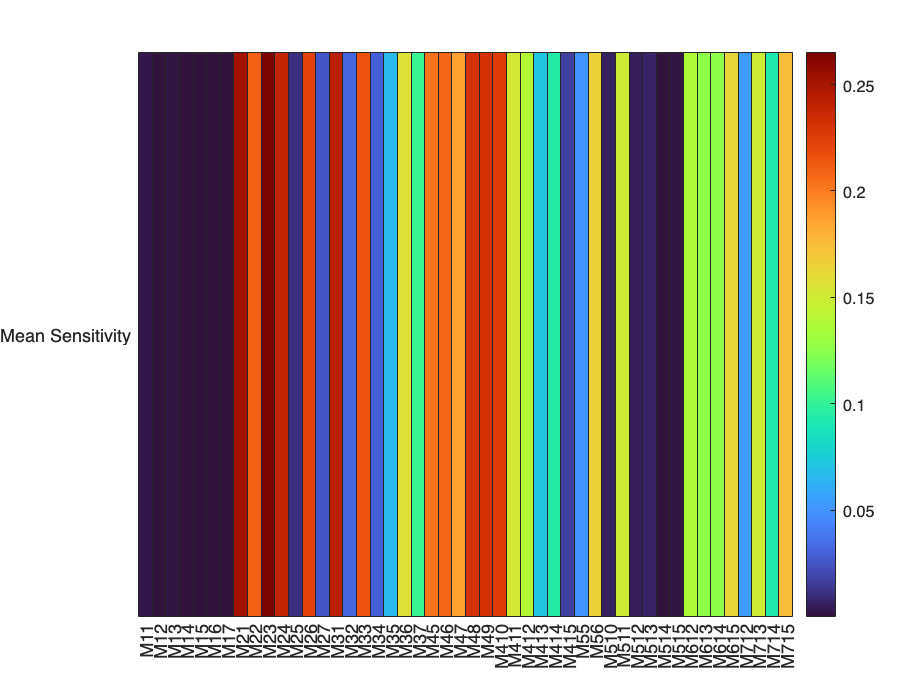

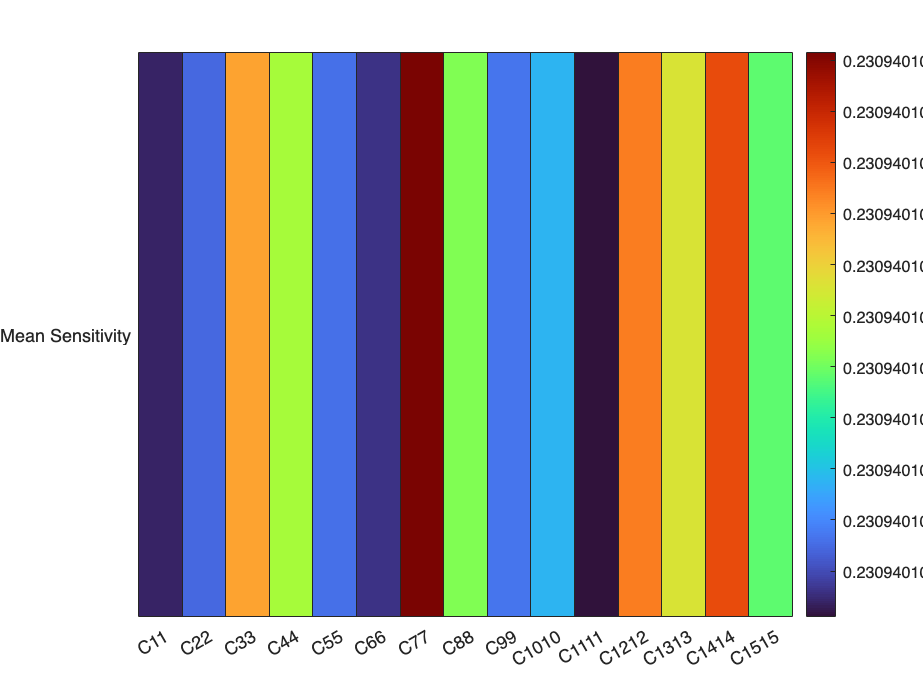

    0.2727



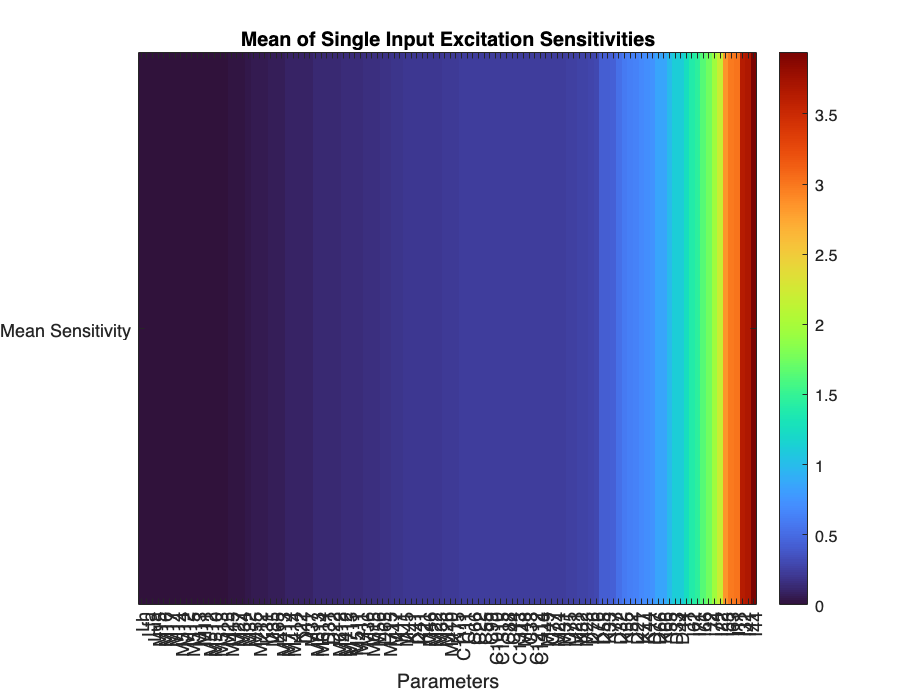

% Go into individual sensitivities
mean_x_plot(SIE_X_Means, "Mean of Single Input Excitation Sensitivities", params_char);

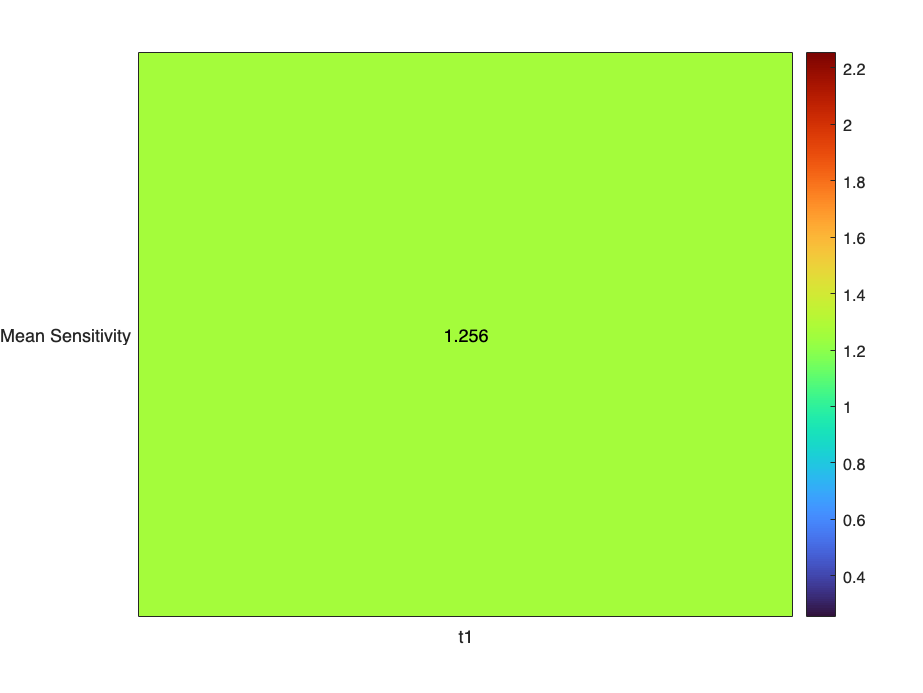

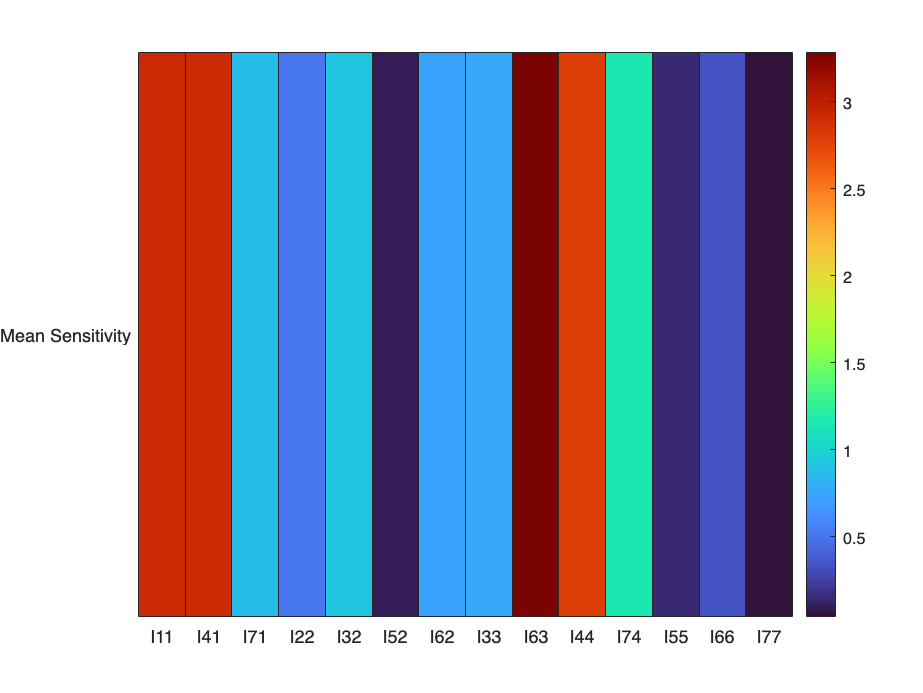

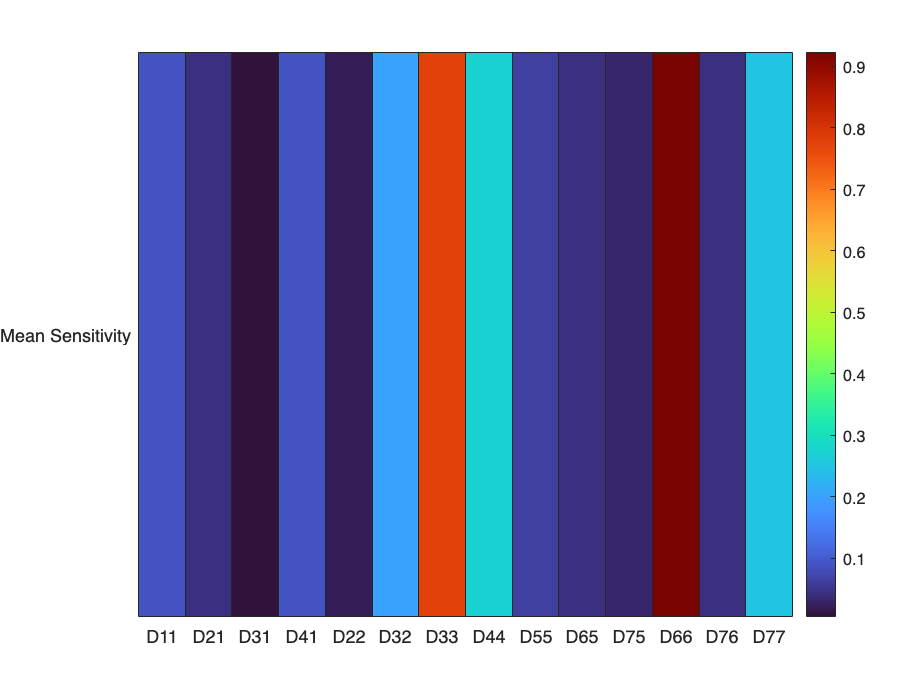

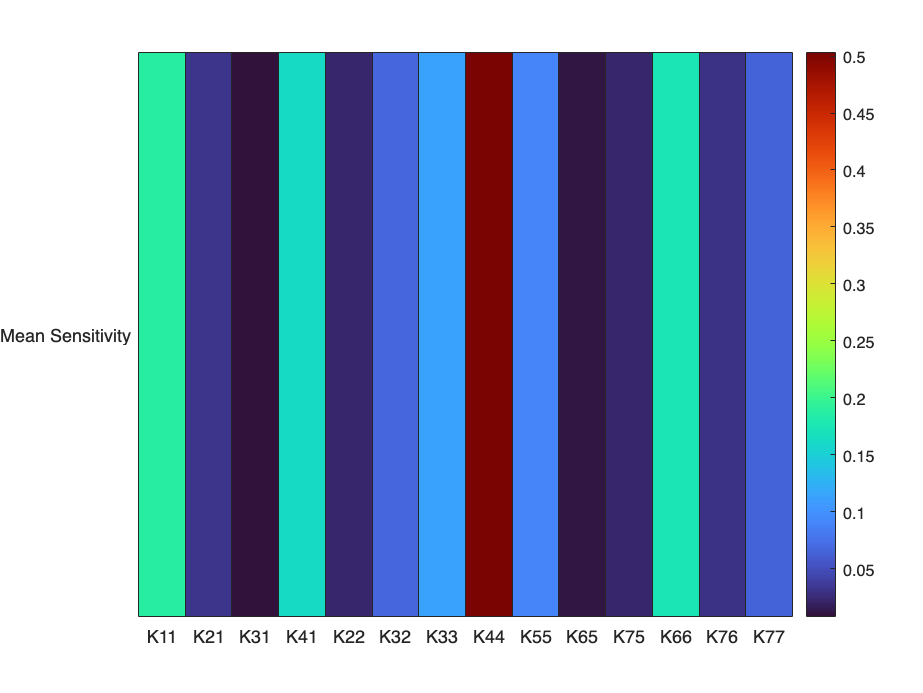

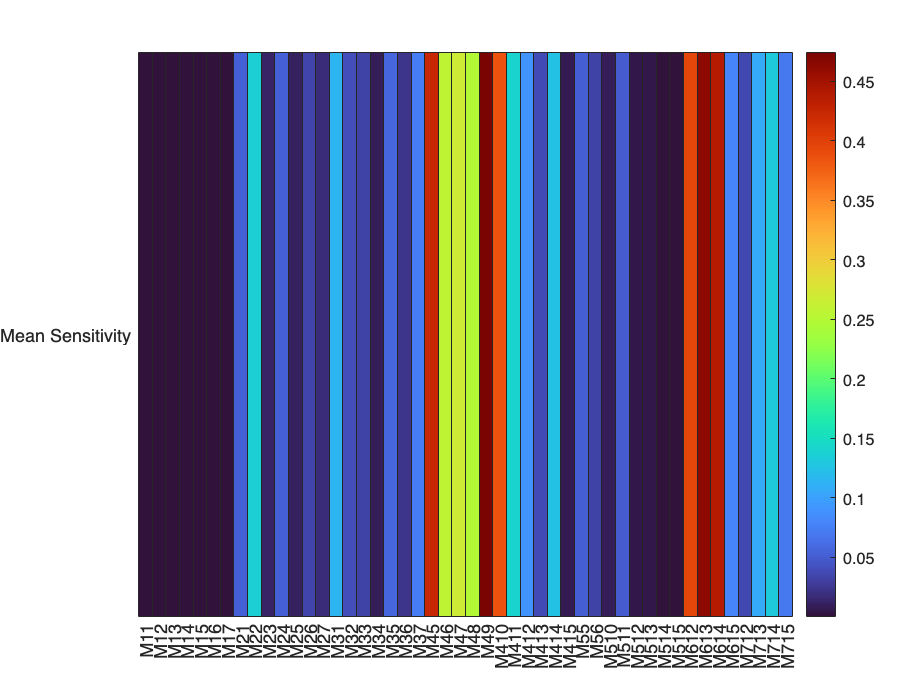

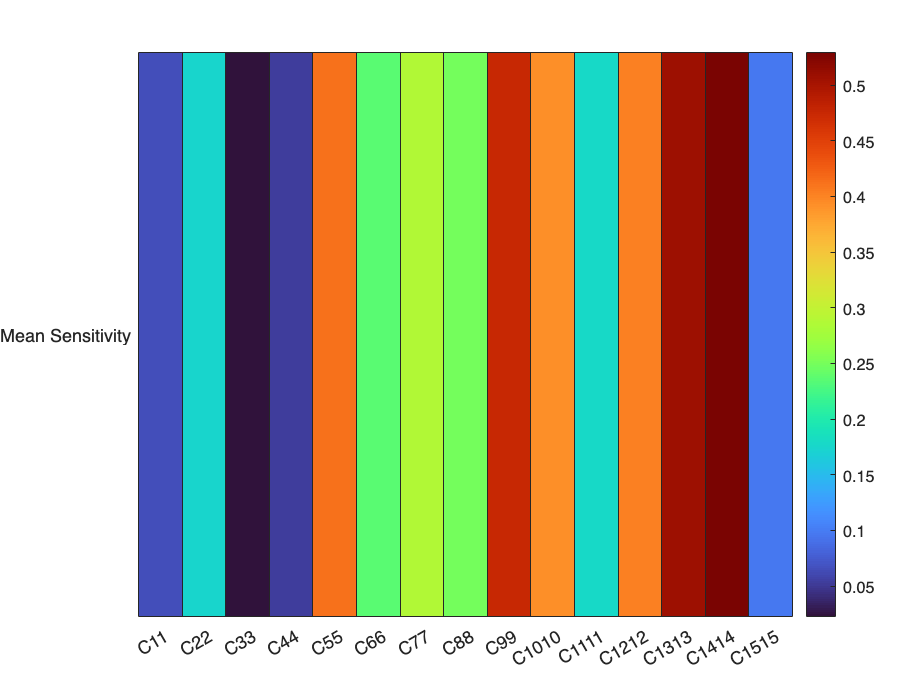

    0.5455



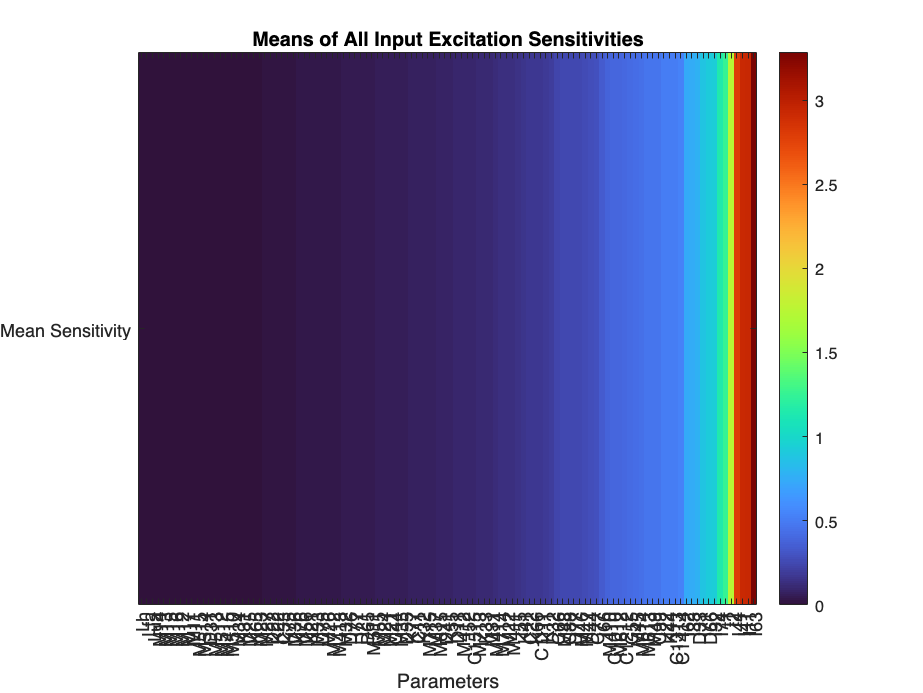

mean_x_plot(AIE_X_Means, "Means of All Input Excitation Sensitivities", params_char);

**SIE Mean Sensitivities for All Muscles**

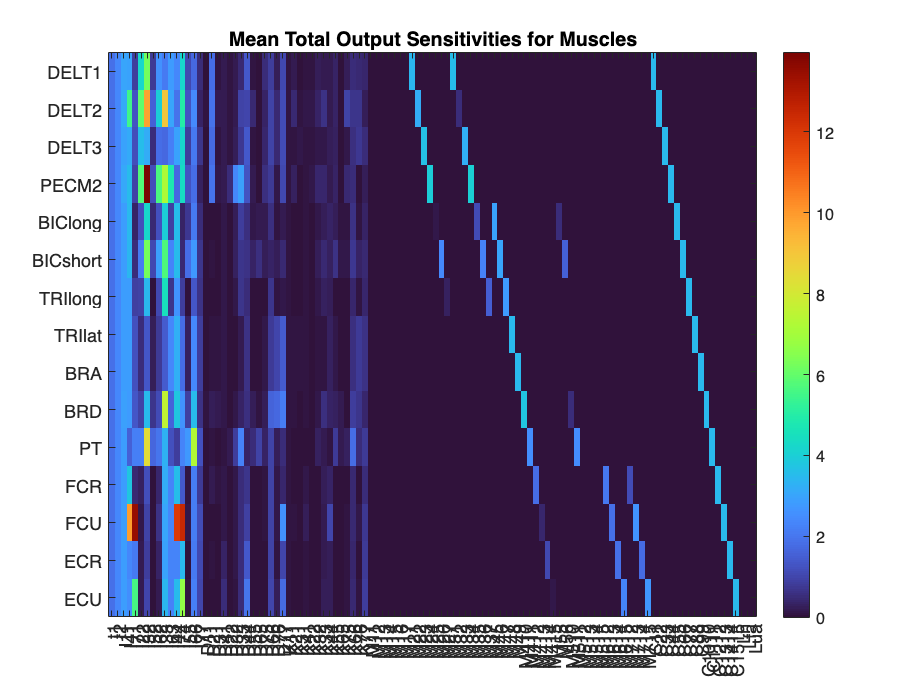

% Take the sensitivities and find the mean of each parameter at each DOF
band_start = 40;
band_end = 80;
means = [];

% ps = parameter sensitivities
for ps = 1:length(SIE_X_Sens) 
    sens = SIE_X_Sens{ps};

    % p = parameter, which corresponds to rows
    for p = 1:size(sens, 1)
        param_sens = [];
        
        % w = the frequency column, do this between the tremor band
        % where the tremor band is between 4-8 Hz
        for w = band_start:band_end
            % Now we need to access individual sensitivity vectors
            param_sens = [param_sens; sens(p, w)];
        end
        params = cell2mat(param_sens);
        means = [means; mean(params)];
    end
end

% Let's plot the data where each column of each row of the `means` will be the y
% and each row corresponds to a parameters
imagesc(means.');
set(gca, 'XTick', 1:numel(params_char), 'XTickLabel', params_char);
set(gca, 'YTick', 1:numel(muscles), 'YTickLabel', muscles);
title("Mean Total Output Sensitivities for Muscles"); 
colormap("turbo");
colorbar;

**SIE Standard Deviation for All Muscles**

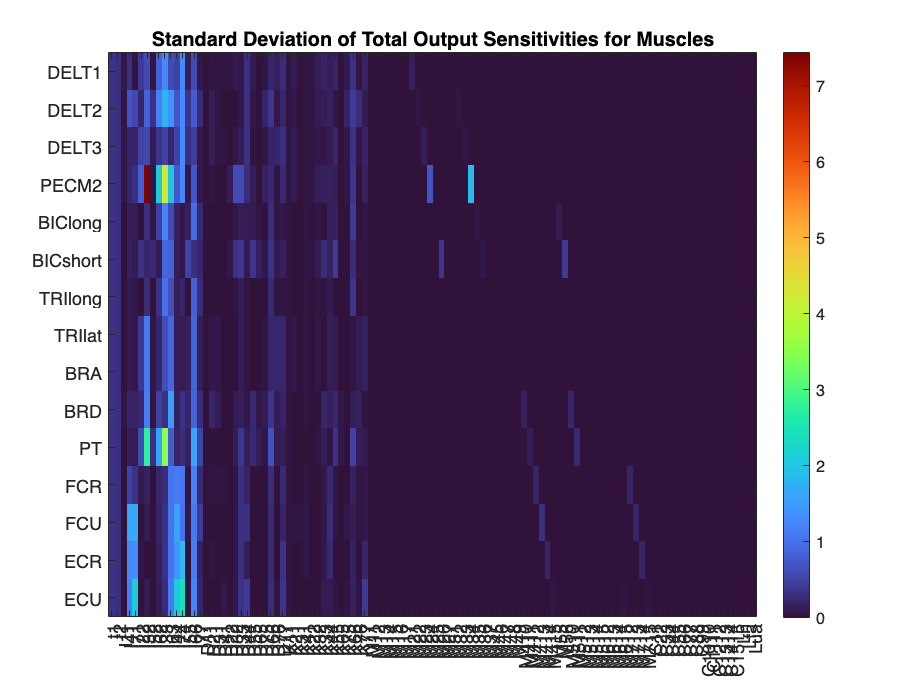

band_start = 40;
band_end = 80;
means = [];

% ps = parameter sensitivities
for ps = 1:length(SIE_X_Sens) 
    sens = SIE_X_Sens{ps};

    % p = parameter, which corresponds to rows
    for p = 1:size(sens, 1)
        param_sens = [];
        
        % w = the frequency column, do this between the tremor band
        % where the tremor band is between 4-8 Hz
        for w = band_start:band_end
            % Now we need to access individual sensitivity vectors
            param_sens = [param_sens; sens(p, w)];
        end
        params = cell2mat(param_sens);
        means = [means; std(params)];
    end
end

% Let's plot the data where each column of each row of the `means` will be the y
% and each row corresponds to a parameters
imagesc(means.');
set(gca, 'XTick', 1:numel(params_char), 'XTickLabel', params_char);
set(gca, 'YTick', 1:numel(muscles), 'YTickLabel', muscles);
title("Standard Deviation of Total Output Sensitivities for Muscles"); 
colormap("turbo");
colorbar;